# Avoid Obstacles Using Reinforcement Learning for Mobile Robots

This example uses Deep Deterministic Policy Gradient (DDPG) based reinforcement learning to develop a strategy for a mobile robot to avoid obstacles. For a brief summary of the DDPG algorithm, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879). 

This example scenario trains a mobile robot to avoid obstacles given range sensor readings that detect obstacles in the map. The objective of the reinforcement learning algorithm is to learn what controls (linear and angular velocity), the robot should use to avoid colliding into obstacles. This example uses an occupancy map of a known environment to generate range sensor readings, detect obstacles, and check collisions the robot may make. The range sensor readings are the observations for the DDPG agent, and the linear and angular velocity controls are the action.

### Load Map

Load a map matrix, `simpleMap`, that represents the environment for the robot.

load Environment3 BW

mapMatrix = BW;
mapScale = 1;

### Range Sensor Parameters

Next, set up a `rangeSensor` object which simulates a noisy range sensor. The range sensor readings are considered observations by the agent. Define the angular positions of the range readings, the max range, and the noise parameters.

scanAngles = -3*pi/8:pi/12:3*pi/8; %angulos lidar
maxRange = 55;%range
lidarNoiseVariance = 0.1^2;
lidarNoiseSeeds = randi(intmax,size(scanAngles));

### Robot Parameters

The action of the agent is a two-dimensional vector $a = [v , \omega] $ where $v$ and $\omega$ are the linear and angular velocities of our robot. The DDPG agent uses normalized inputs for both the angular and linear velocities, meaning the actions of the agent are a scalar between -1 and 1, which is multiplied by the `maxLinSpeed` and `maxAngSpeed` parameters to get the actual control. Specify this maximum linear and angular velocity.

Also, specify the initial position of the robot as `[x y theta]`.

% Max speed parameters
maxLinSpeed = 0.9; %lineal speed
maxAngSpeed = 0.9; %angular speed

%%%%route1envieronment1%%%%%
initX = 135; %start point x
initY =27; %start point y
%%%%%%%%%%%%%%
initTheta = pi;%ang init

### Show Map and Robot Positions

To visualize the actions of the robot, create a figure. Start by showing the occupancy map and plot the initial position of the robot.

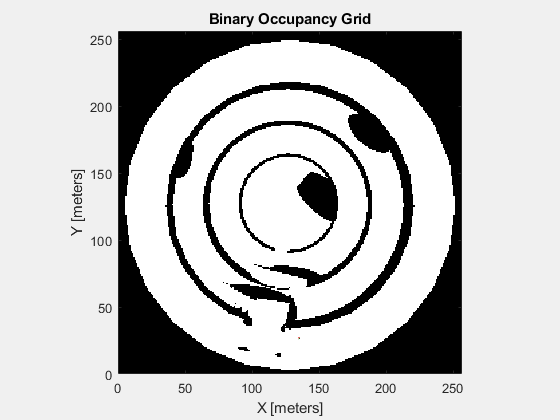

fig = figure("Name","BW");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(mapMatrix),"Parent",ax);
hold on
plotTransforms([initX,initY,0],eul2quat([initTheta,0,0]),"MeshFilePath","groundvehicle.stl","View","2D");
light;
hold off

### Environment Interface

Create an environment model that takes the action, and gives the observation and reward signals. Specify the provided example model name, ex`ampleHelperAvoidObstaclesMobileRobot`, the simulation time parameters, and the agent block name.

mdl = "exampleHelperAvoidObstaclesMobileRobot";
Tfinal = 1000;
sampleTime = 0.1;

agentBlk = mdl + "/Agent";

Open the model.

open_system(mdl)

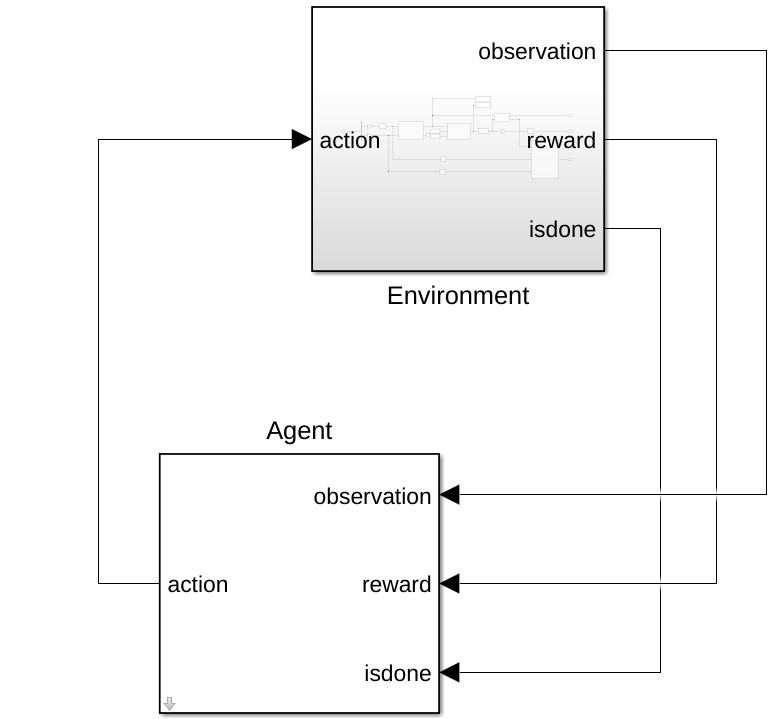

The model contains the `Environment` and `Agent` blocks. The `Agent` block is not defined yet.

Inside the `Environment` Subsystem block, you should see a model for simulating the robot and sensor data. The subsystem takes in the action, generates the observation signal based on the range sensor readings, and calculates the reward based on the distance from obstacles, and the effort of the action commands.

open_system(mdl + "/Environment")

Define observation parameters, `obsInfo`, using the `rlNumericSpec` object and giving the lower and upper limit for the range readings with enough elements for each angular position in the range sensor.

obsInfo = rlNumericSpec([numel(scanAngles) 1],...
    "LowerLimit",zeros(numel(scanAngles),1),...
    "UpperLimit",ones(numel(scanAngles),1)*maxRange);
numObservations = obsInfo.Dimension(1);

Define action parameters, `actInfo`. The action is the control command vector, $a = [v , \omega] $, normalized to $[-1, 1]$.

numActions = 2;
actInfo = rlNumericSpec([numActions 1],...
    "LowerLimit",-1,...
    "UpperLimit",1);

Build the environment interface object using [`rlSimulinkEnv`](docid:rl_ref.mw_12cc40dc-3191-4a23-af71-1625696c1a14). Specify the model, agent block name, observation parameters, and action parameters. Set the reset function for the simulation using `exampleHelperRLAvoidObstaclesResetFcn`. This function restarts the simulation by placing the robot in a new random location to begin avoiding obstacles. 

env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo);
env.ResetFcn = @(in)exampleHelperRLAvoidObstaclesResetFcn(in,scanAngles,maxRange,mapMatrix);
env.UseFastRestart = "On";

For another example that sets up a Simulink® environment for training, see [Create Simulink Environment and Train Agent](docid:rl_ug.mw_873bd3fc-b713-4e71-b776-9758762d592c).

## DDPG Agent

A DDPG agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the observation and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

statePath = [
    featureInputLayer(numObservations, "Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","CriticStateFC1")
    reluLayer("Name","CriticRelu1")
    fullyConnectedLayer(25,"Name","CriticStateFC2")];
actionPath = [
    featureInputLayer(numActions,"Normalization","none","Name","Action")
    fullyConnectedLayer(25,"Name","CriticActionFC1")];
commonPath = [
    additionLayer(2,"Name","add")
    reluLayer("Name","CriticCommonRelu")
    fullyConnectedLayer(1,"Name","CriticOutput")];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,"CriticStateFC2","add/in1");
criticNetwork = connectLayers(criticNetwork,"CriticActionFC1","add/in2");
criticNetwork = dlnetwork(criticNetwork);

Next, specify options for the critic optimizer using `rlOptimizerOptions`.

Finally, create the critic representation using the specified deep neural network and options. You must also specify the action and observation specifications for the critic, which you obtain from the environment interface. For more information, see [rlQValueFunction](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701).

criticOptions = rlOptimizerOptions("LearnRate",1e-3,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,"ObservationInputNames","State","ActionInputNames","Action");

A DDPG agent decides which action to take given observations using an actor representation. To create the actor, first create a deep neural network with one input, the observation, and one output, the action.

Finally, construct the actor in a similar manner as the critic. For more information, see [`rlContinuousDeterministicActor`](docid:rl_ref#mw_c2909424-90f4-4a52-803b-73310483e6c3).

actorNetwork = [
    featureInputLayer(numObservations,"Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","actorFC1")
    reluLayer("Name","actorReLU1")
    fullyConnectedLayer(50, "Name","actorFC2")
    reluLayer("Name","actorReLU2")
    fullyConnectedLayer(2, "Name","actorFC3")
    tanhLayer("Name","Action")];
actorNetwork = dlnetwork(actorNetwork);

actorOptions = rlOptimizerOptions("LearnRate",1e-4,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

### Create DDPG agent object

Specify the agent options.

agentOpts = rlDDPGAgentOptions(...
    "SampleTime",sampleTime,...
    "ActorOptimizerOptions",actorOptions,...
    "CriticOptimizerOptions",criticOptions,...
    "DiscountFactor",0.995, ...
    "MiniBatchSize",128, ...
    "ExperienceBufferLength",1e6); 

agentOpts.NoiseOptions.Variance = 0.1;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

Create the `rlDDPGAgent` object. The `obstacleAvoidanceAgent` variable is used in the model for the `Agent` block.

obstacleAvoidanceAgent = rlDDPGAgent(actor,critic,agentOpts);
open_system(mdl + "/Agent")

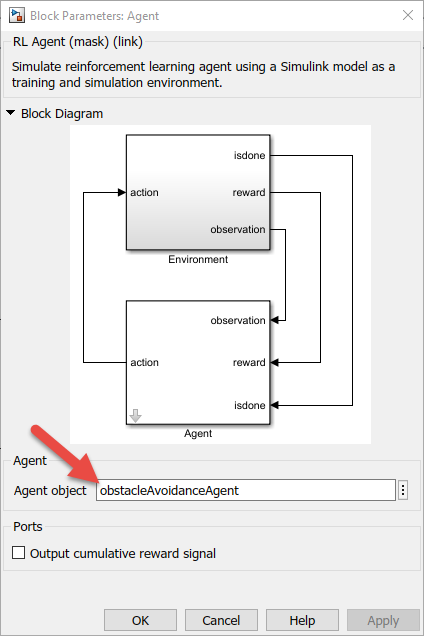

## Reward

The reward function for the agent is modeled as shown.

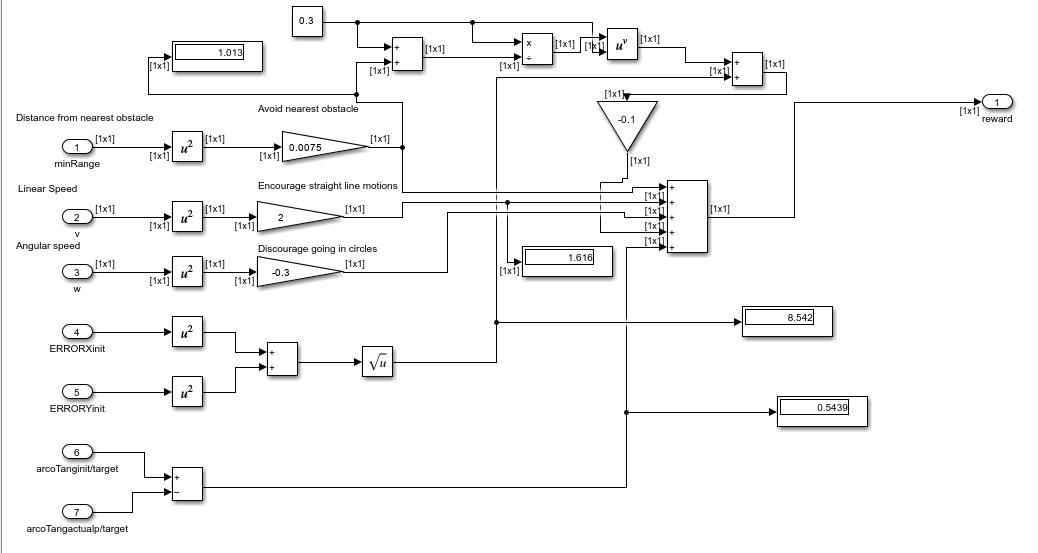

The agent is rewarded to avoid the nearest obstacle, which minimizes the worst-case scenario. Additionally, the agent is given a positive reward for higher linear speeds, and is given a negative reward for higher angular speeds. This rewarding strategy discourages the agent's behavior of going in circles. Tuning your rewards is key to properly training an agent, so your rewards vary depending on your application.

## Train Agent

maxEpisodes = 2500;
maxSteps = ceil(Tfinal/sampleTime);
trainOpts = rlTrainingOptions(...
    "MaxEpisodes",maxEpisodes, ...
    "MaxStepsPerEpisode",maxSteps, ...
    "ScoreAveragingWindowLength",50, ...
    "StopTrainingCriteria","AverageReward", ...
    "StopTrainingValue",99999, ...
    "Verbose", true, ...
    "Plots","training-progress");

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally-intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true; % Toggle this to true for training. 

if doTraining
    % Train the agent.
    trainingStats = train(obstacleAvoidanceAgent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load exampleHelperAvoidObstaclesAgent obstacleAvoidanceAgent
end

Episode:   1/2500 | Episode reward: -22845.30 | Episode steps: 10000 | Average reward: -22845.30 | Step Count: 10000 | Episode Q0:    -0.07
Episode:   2/2500 | Episode reward: -5749.51 | Episode steps: 8077 | Average reward: -14297.40 | Step Count: 18077 | Episode Q0:    -1.87
Episode:   3/2500 | Episode reward: -1144.14 | Episode steps:  449 | Average reward: -9912.98 | Step Count: 18526 | Episode Q0:    -1.20
Episode:   4/2500 | Episode reward: -1830.26 | Episode steps:  739 | Average reward: -7892.30 | Step Count: 19265 | Episode Q0:    -2.13
Episode:   5/2500 | Episode reward:  7456.18 | Episode steps: 10000 | Average reward: -4822.61 | Step Count: 29265 | Episode Q0:    -2.13
Episode:   6/2500 | Episode reward: -3768.18 | Episode steps: 5766 | Average reward: -4646.87 | Step Count: 35031 | Episode Q0:    -0.92
Episode:   7/2500 | Episode reward:  -681.35 | Episode steps:  302 | Average reward: -4080.37 | Step Count: 35333 | Episode Q0:    -0.72
Episode:   8/2500 | Episode reward: 

## Simulate

Use the trained agent to simulate the robot driving in the map and avoiding obstacles.

set_param("exampleHelperAvoidObstaclesMobileRobot","StopTime","1000");
out = sim("exampleHelperAvoidObstaclesMobileRobot.slx");

## Visualize

To visualize the simulation of the robot driving around the environment with range sensor readings, use the helper, `exampleHelperAvoidObstaclesPosePlot`.

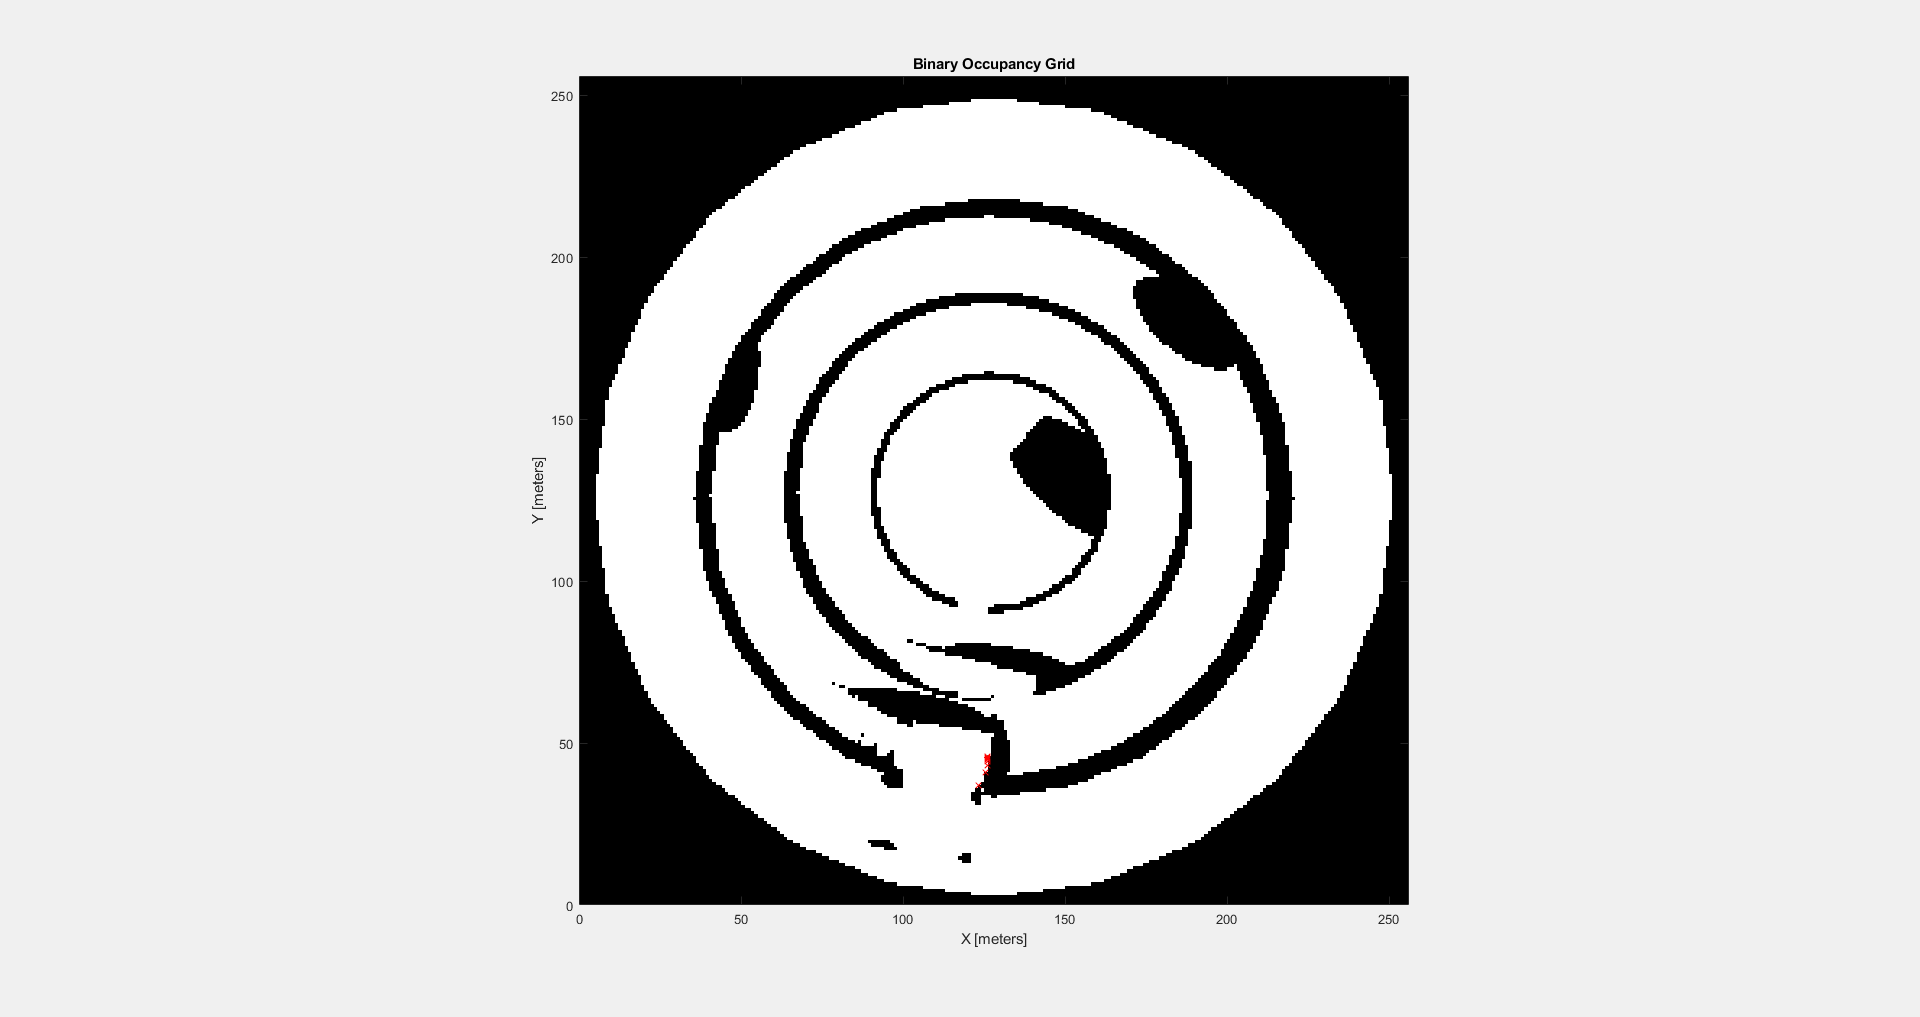

for i = 1:5:size(out.range,3)
   u = out.pose(i,:);
   r = out.range(:,:,i);
   exampleHelperAvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
end

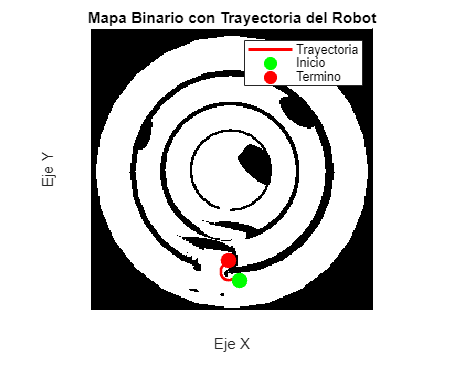

% Crear una figura
figure;

% Invertir los valores del mapa binario
BW_inverted = imcomplement(BW);

% Mostrar el mapa binario invertido como una imagen de fondo
imshow(BW_inverted);
hold on; % Mantener el gráfico actual para superponer la trayectoria

% Definir los límites del gráfico usando las dimensiones de tu mapa 2D
xLimits = [1 size(BW, 2)];
yLimits = [1 size(BW, 1)];
xlim(xLimits);
ylim(yLimits);

% Crear una matriz vacía para almacenar la trayectoria del robot
trajectory = [];

% Iterar a través de los datos de la trayectoria y trazar la trayectoria del robot
for i = 1:5:size(out.range,3)
    u = out.pose(i,:);
    % Ajustar las coordenadas del eje Y
    u(2) = (-1) * (u(2) - 256);
    % Aquí puedes realizar cualquier otra operación necesaria con 'u'
    trajectory = [trajectory; u];
end

% Trazar la trayectoria en el mapa 2D
plot(trajectory(:,1), trajectory(:,2), 'r-', 'LineWidth', 2);

% Etiquetas y título
xlabel('Eje X');
ylabel('Eje Y');
title('Mapa Binario con Trayectoria del Robot');

% Marcar el punto de inicio con color verde
startPoint = trajectory(1,:);
plot(startPoint(1), startPoint(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');

% Marcar el punto de termino con color rojo
endPoint = trajectory(end,:);
plot(endPoint(1), endPoint(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Mostrar la leyenda
legend('Trayectoria', 'Inicio', 'Termino');

% Habilitar la cuadrícula
grid on;


% Desactivar el modo de espera para permitir que la figura se muestre correctamente
drawnow;